# Evaluation of Forecast Hub for US state-level COVID-19 forecasts

**[Updated Jan 3rd, 2020]**

The following shows the mean absolute error of forecasts produced by various teams.

The forecasting teams submit their forecasts to [https://github.com/reichlab/covid19-forecast-hub/](https://github.com/reichlab/covid19-forecast-hub/tree/master/data-processed)

These forecasts can be visualized at [https://viz.covid19forecasthub.org/](https://viz.covid19forecasthub.org/)

## Data for evaluation

We use the latest JHU data as the ground truth. 

clc, clear all, close all
warning off;
load_data_us;

lastday = size(data_4, 2)-1; 
firstday = 160;
skipdays = 7;

time_stamps =(firstday:lastday);
data_src = {'JHU'}; % Next we list methods that use these data sources in order

defpath = '../results/others_death_forecasts/biweekly_reports/state-case';
xx = cellstr(ls([defpath '/*.csv']));
yy = unique(cellfun(@(x)(x(1:end-8)), xx, 'UniformOutput', false));
methods_cases = yy(contains(yy, 'reich')| startsWith(yy, 'USC_SI') | startsWith(yy, 'Karlen'));

defpath = '../results/others_death_forecasts/biweekly_reports/state-death';
xx = cellstr(ls([defpath '/*.csv']));
yy = [unique(cellfun(@(x)(x(1:end-8)), xx, 'UniformOutput', false))];
methods_deaths = yy(contains(yy, 'reich')| startsWith(yy, 'USC_SI') | startsWith(yy, 'Karlen'));
%fprintf('Loaded %d methods', length(yy));

% Loading other forecasts
    methods = methods_deaths;
    defpath = '../results/others_death_forecasts/biweekly_reports/state-death';
    for mm = 1:length(methods)
        num_files = 0;        
        for tt = 1:length(time_stamps)
            try
                fname = [methods{mm}, '_', num2str(time_stamps(tt)+1), '.csv'];
                preds = readtable([defpath '/', fname]);
                preds = preds{1:end, 3:end};
                preds(1, 1) = preds(1, 1) - 1; % Correcting the discrepancy in date labeling
                eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
                num_files = num_files + 1;
            catch
                eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
            end
        end
        %disp(['Loaded' num2str(num_files) ' for ', methods{mm}]);
    end
        methods = methods_cases;
    defpath = '../results/others_death_forecasts/biweekly_reports/state-case';
    for mm = 1:length(methods)
        num_files = 0;        
        for tt = 1:length(time_stamps)
            try
                fname = [methods{mm}, '_', num2str(time_stamps(tt)+1), '.csv'];
                preds = readtable([defpath '/', fname]);
                preds = preds{1:end, 3:end};
                preds(1, 1) = preds(1, 1) - 1; % Correcting the discrepancy in date labeling
                eval([methods{mm}, '{',  num2str(tt),'} = ', 'preds;']);
                num_files = num_files + 1;
            catch
                eval([methods{mm}, '{',  num2str(tt),'} = ', '-1;']);
            end
        end
        %disp(['Loaded' num2str(num_files) ' for ', methods{mm}]);
    end

a_sunday = 94;
first_tt = 1;
cidx = popu > -1;
cidx([51, 52, 53, 55, 56]) = 0; % Others do not forecast for these states
all_sundays = (firstday+7-mod(firstday-a_sunday, 7)):7:size(data_4, 2); % All sundays in the data
sun_map = containers.Map(all_sundays, 1:length(all_sundays));

methods = methods_cases;
sunday_gt  = [(a_sunday+7:7:size(data_4, 2));diff(data_4(:, a_sunday:7:end)')'];
for mm = 1:length(methods)
    err_mat = nan(lastday-firstday+1, length(all_sundays));
    err_mat1 = err_mat;
    for tt=first_tt:length(time_stamps)
        pred_files = eval([methods{mm} '{' num2str(tt) '}']);
        
        if length(pred_files) == 1 && tt<length(time_stamps)
            pred_files = eval([methods{mm} '{' num2str(tt+1) '}']);
            if length(pred_files) == 1
                continue;
            end
        end
        rem_idx = pred_files(1, :) > size(data_4, 2); % If the data has not been observed, remove the prediction
        pred_files(:, rem_idx) = [];
        pred_dates = pred_files(1, 2:end);
        
        if length(pred_dates) < 1 % This means only the base deaths are left, no forecast to evaluate
            continue;
        end
        
        if any(diff(pred_dates) ~= 7) && length(pred_dates)>1
            continue;
        end
        
        gt_start = find(sunday_gt(1, :) == pred_dates(1)); % sundays on or after predicted days
        
        if length(gt_start)<1
            continue;
        end
        
        gt = sunday_gt(logical([0; cidx]), int32(gt_start(1):1:gt_start(1)+length(pred_dates)-1));
        preds = pred_files(2:end, 2:end);
        preds = (preds(cidx, :) + abs(preds(cidx, :)))/2;
        err_vec = nanmean(2*abs(gt-preds)./abs(gt+preds), 1);
        err_vec1 = nanmean(abs(gt-preds), 1);
        if any(isinf(err_vec))
            fprintf('.');
        end
        
        mapped_vec = arrayfun(@(x)sun_map(x), pred_dates);
        err_mat(tt, mapped_vec) = err_vec;
        err_mat1(tt, mapped_vec) = err_vec1;
    end
    eval(['MAE_' methods{mm}  '= err_mat1;']);
end

methods = methods_deaths;
sunday_gt  = [(a_sunday+7:7:size(deaths, 2));diff(deaths(:, a_sunday:7:end)')'];
for mm = 1:length(methods)
    err_mat = nan(lastday-firstday+1, length(all_sundays));
    err_mat1 = err_mat;
    for tt=first_tt:length(time_stamps)
        pred_files = eval([methods{mm} '{' num2str(tt) '}']);
        
        if length(pred_files) == 1 && tt<length(time_stamps)
            pred_files = eval([methods{mm} '{' num2str(tt+1) '}']);
            if length(pred_files) == 1
                continue;
            end
        end
        rem_idx = pred_files(1, :) > size(data_4, 2); % If the data has not been observed, remove the prediction
        pred_files(:, rem_idx) = [];
        pred_dates = pred_files(1, 2:end);
        
        if length(pred_dates) < 1 % This means only the base deaths are left, no forecast to evaluate
            continue;
        end
        
        if any(diff(pred_dates) ~= 7) && length(pred_dates)>1
            continue;
        end
        
        gt_start = find(sunday_gt(1, :) == pred_dates(1)); % sundays on or after predicted days
        
        if length(gt_start)<1
            continue;
        end
        
        gt = sunday_gt(logical([0; cidx]), int32(gt_start(1):1:gt_start(1)+length(pred_dates)-1));
        preds = pred_files(2:end, 2:end);
        preds = (preds(cidx, :) + abs(preds(cidx, :)))/2;
        err_vec = nanmean(2*abs(gt-preds)./abs(gt+preds), 1);
        err_vec1 = nanmean(abs(gt-preds), 1);
        if any(isinf(err_vec))
            fprintf('.');
        end
        
        mapped_vec = arrayfun(@(x)sun_map(x), pred_dates);
        err_mat(tt, mapped_vec) = err_vec;
        err_mat1(tt, mapped_vec) = err_vec1;
    end
    eval(['MAE_' methods{mm}  '= err_mat1;']);
end


methods = [methods_cases; methods_deaths];
for mm=1:length(methods)
    err_mat1 = eval(['MAE_' methods{mm}]);
    tot_ahead = 4;
    ahead_error = nan(tot_ahead, size(err_mat1, 1));
    for aidx = 1:tot_ahead
        for tt=first_tt:length(time_stamps)
            sun_lb = time_stamps(tt) + aidx*7 - 1;
            sun_ub = time_stamps(tt) + aidx*7 + 5;
            sun_idx = find(all_sundays >= sun_lb & all_sundays <= sun_ub);
            
            if ~isempty(sun_idx)
               ahead_error(aidx, tt) = err_mat1(tt, sun_idx(1)); 
            end
        end
    end
    eval(['ahead_error_' methods{mm} ' = ahead_error;']);
end


## Submission Selection

Since this hub receives many submissions we select only some of them to show in the evaluation. To qualify, the team must have at least one submission in the last 5 weeks AND should have been in top 5 more than two weeks (separately for death forecasts and case forecasts).


% Filter based on 4-week-ahead. To qualify, a method must be in top-5 at
% least one week of its lifetime.
methods = methods_deaths;
all_err4 = nan(length(all_sundays), length(methods));
for mm=1:length(methods)
    for tt=1:length(all_sundays)
        tidx = all_sundays(tt)-firstday+1;
        eval(['thiserr = ahead_error_' methods{mm} ';']);
        try
        if ~isnan(thiserr(4, tidx))
            all_err4(tt, mm) = thiserr(4, tidx);
        elseif ~isnan(thiserr(4, tidx+1))
            all_err4(tt, mm) = thiserr(4, tidx+1);
        end
        catch
            continue;
        end
    end
end

all_err4(all(isnan(all_err4), 2), :) = [];
all_err4(isnan(all_err4)) = Inf;

m_rank = all_err4;
for tt = 1:size(all_err4, 1)
    [~, ~, rr] = unique(all_err4(tt, :));
    m_rank(tt, :) = rr;
end
death_methods = (sum(m_rank <= 5, 1)>2);

% Only show CU_select instead of other scenarios of CU_
death_methods(startsWith(methods, 'reich_CU') & ~contains(methods, 'select')) = 0; 



methods = methods_cases;
all_err4 = nan(length(all_sundays), length(methods));
for mm=1:length(methods)
    for tt=1:length(all_sundays)
        tidx = all_sundays(tt)-firstday+1;
        eval(['thiserr = ahead_error_' methods{mm} ';']);
        try
        if ~isnan(thiserr(4, tidx))
            all_err4(tt, mm) = thiserr(4, tidx);
        elseif ~isnan(thiserr(4, tidx+1))
            all_err4(tt, mm) = thiserr(4, tidx+1);
        end
        catch
            continue;
        end
    end
end

all_err4(all(isnan(all_err4), 2), :) = [];
all_err4(isnan(all_err4)) = Inf;

m_rank = all_err4;
for tt = 1:size(all_err4, 1)
    [~, ~, rr] = unique(all_err4(tt, :));
    m_rank(tt, :) = rr;
end

case_methods = (sum(m_rank <= 5, 1)>2);
% Only show CU_select instead of other scenarios of CU_
case_methods(startsWith(methods, 'reich_CU') & ~contains(methods, 'select')) = 0; 

## Errors for US states death forecasts

Jump to:  US states death forecasts; US states case forecasts

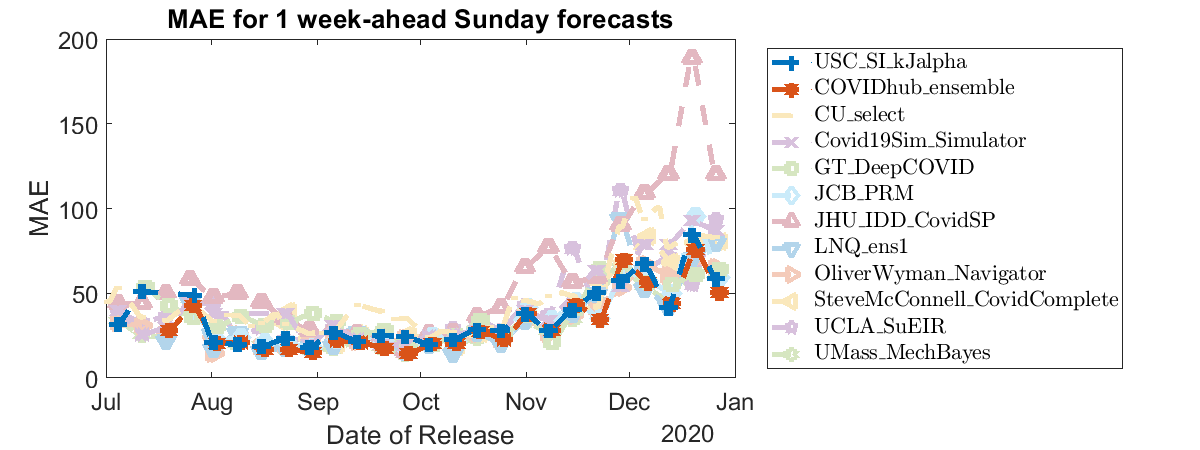

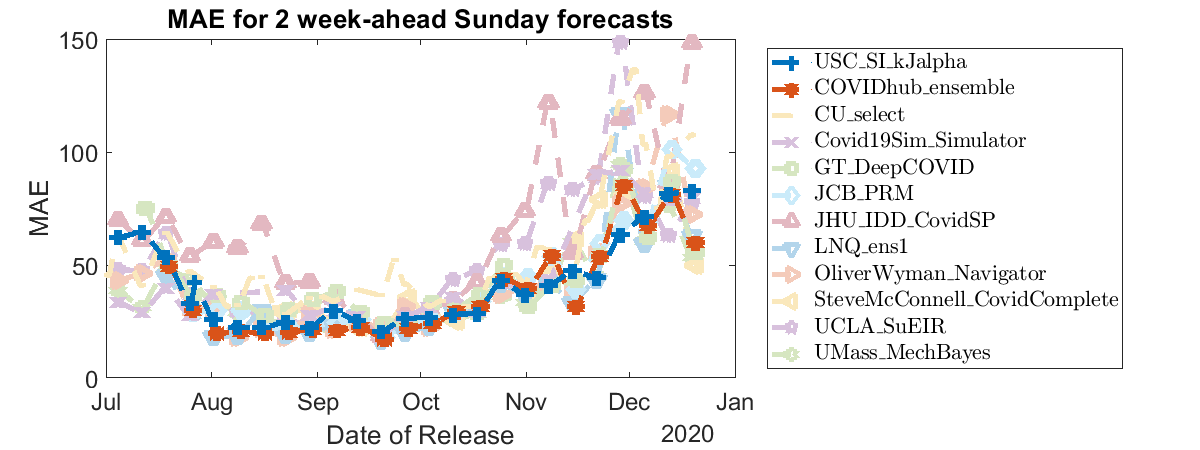

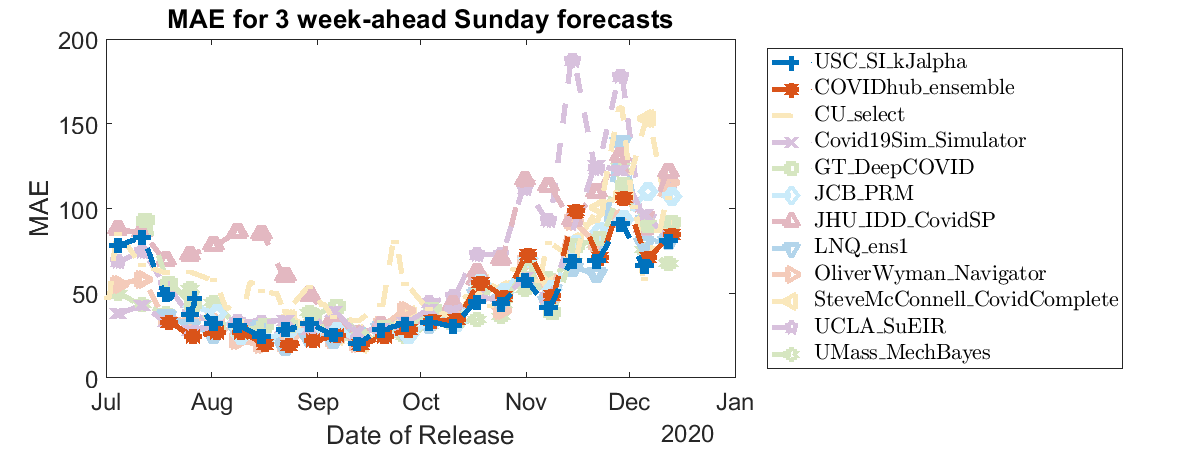

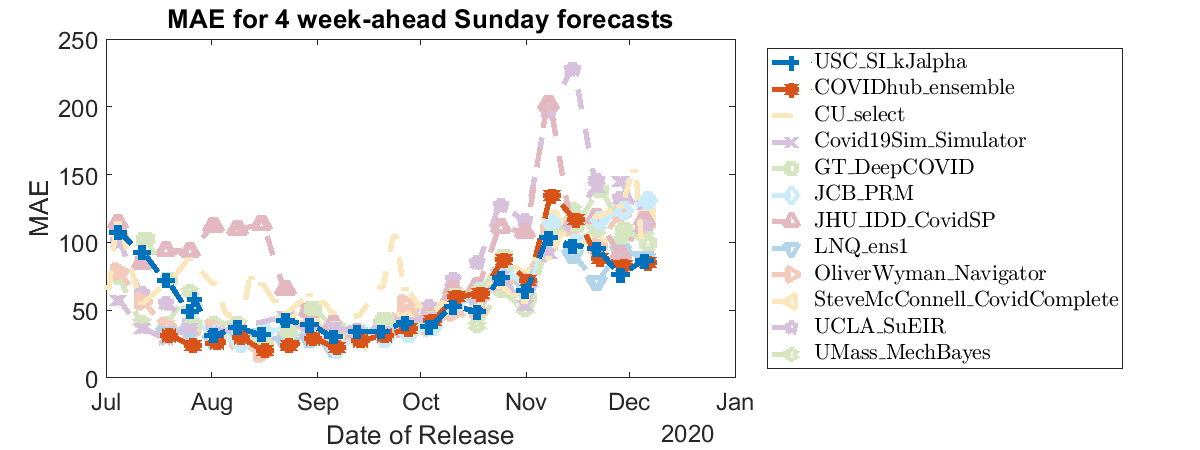

methods = methods_deaths(death_methods);
all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};
highlight_idx = 0.3*ones(length(methods), 1);
sel_methods = [find(startsWith(methods, 'USC_SI_kJalpha_state')); find(contains(methods, 'COVIDhub'))];
highlight_idx(sel_methods) = 1;
reorder_idx = [sel_methods; find(highlight_idx<1)];

for aidx = 1:4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['ahead_error = ahead_error_' methods{mm} ';']);
        errs = ahead_error(aidx, :);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = datetime(2020, 1, 23)+ caldays(time_stamps);
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm1, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    
    hold off;
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$'); ll = strrep(ll, 'reich_', ''); ll = strrep(ll, '_state_death', '');
    ll = strrep(ll, '_', '\_');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder));
end

## Errors for US states case forecasts

Jump to:  US states death forecasts; US states case forecasts

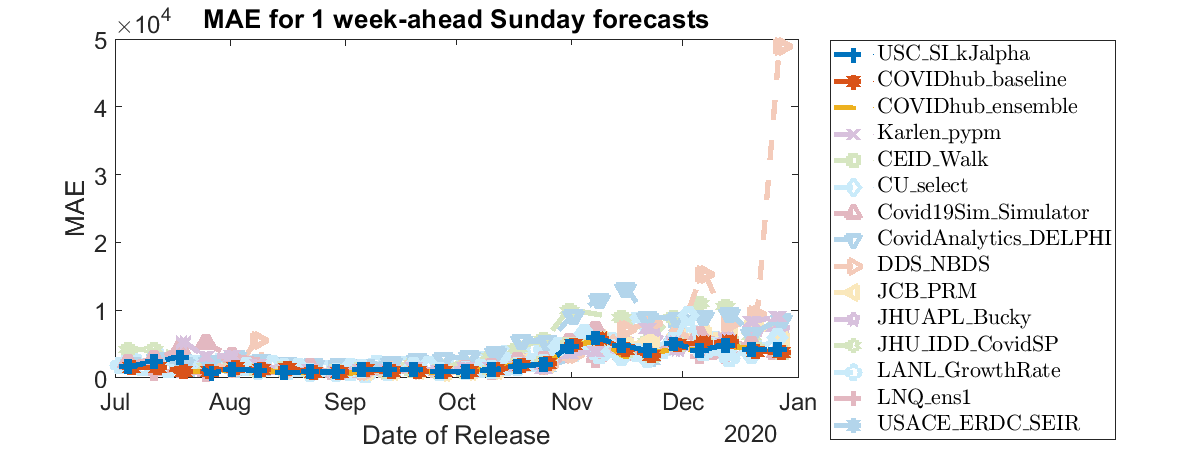

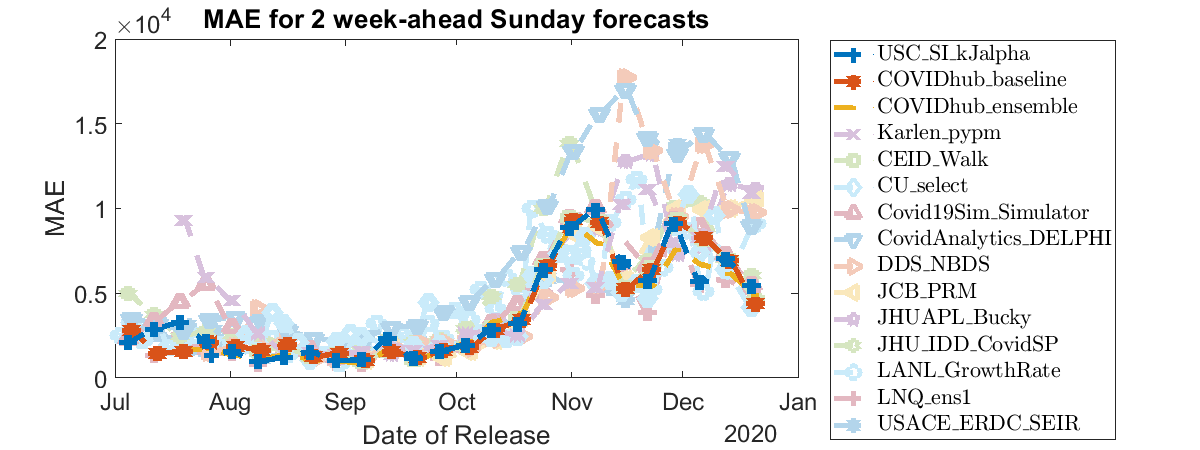

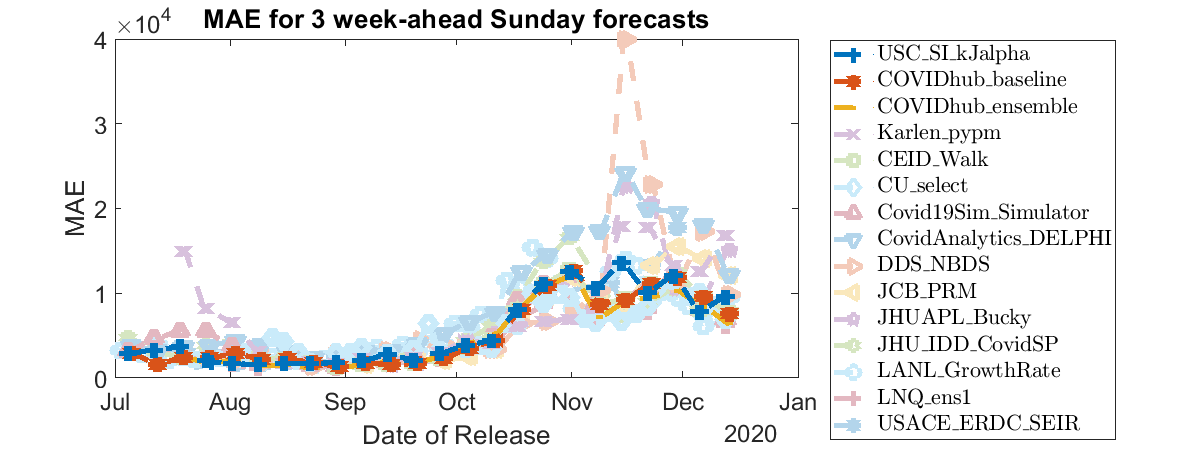

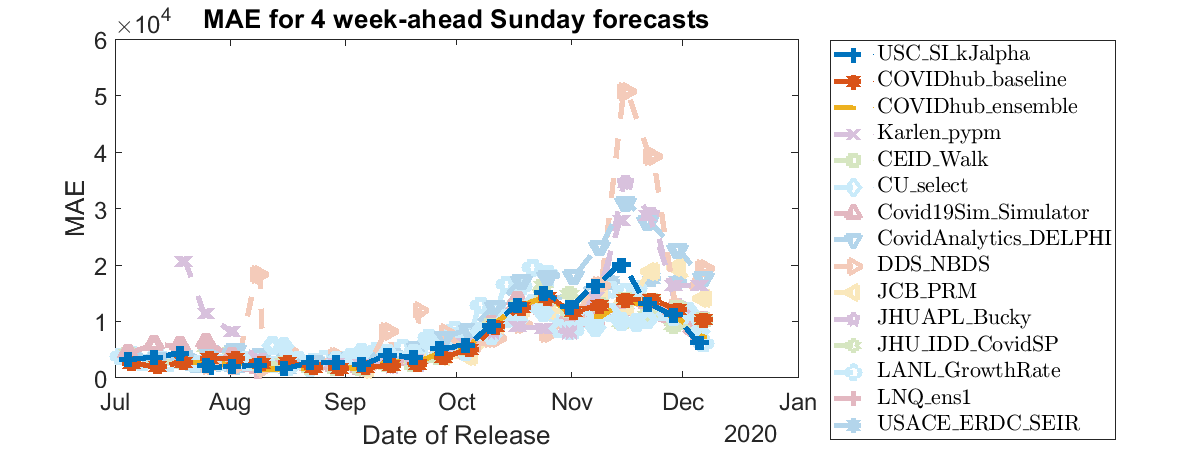

methods = methods_cases(case_methods);
all_marks = {'o','+','*','.','x','s','d','^','v','>','<','p','h'};
highlight_idx = 0.3*ones(length(methods), 1);
sel_methods = [find(startsWith(methods, 'USC_SI_kJalpha_state')); find(contains(methods, 'COVIDhub'))];
highlight_idx(sel_methods) = 1;
reorder_idx = [sel_methods; find(highlight_idx<1)];

for aidx = 1:4
    figure('DefaultAxesFontSize',18);
    set(gcf,'position',[10,10,1200,450]);
    ll = {};
    hh = zeros(length(methods), 1);
    for mm1=1:length(methods)
        mm = reorder_idx(mm1);
        eval(['ahead_error = ahead_error_' methods{mm} ';']);
        errs = ahead_error(aidx, :);
        nnanidx = ~isnan(errs);
        if sum(nnanidx)<1
            continue;
        end
        Tx = datetime(2020, 1, 23)+ caldays(time_stamps);
        p1 = plot(Tx(nnanidx), errs(nnanidx), 'Marker', all_marks{1+mod(mm1, 13)}, 'LineStyle',"--", 'LineWidth', 4, 'MarkerSize', 10);
        p1.Color  = 1 - highlight_idx(mm).*(1-p1.Color);
        hh(mm1) = p1;
        hold on;
        ll = [ll; methods{mm}];
    end
    title(['MAE for ' num2str(aidx) ' week-ahead Sunday forecasts']);
    xlabel('Date of Release');
    ylabel('MAE');
    
    hold off;
    ll = strrep(ll, 'SIkJa', 'SIkJ$\alpha$'); ll = strrep(ll, 'reich_', ''); ll = strrep(ll, '_state_case', '');
    ll = strrep(ll, '_', '\_');
    legend(ll, "Interpreter","latex", 'location', 'eastoutside');
    
    set(gca, 'Children', fliplr(hh(hh>0)));
    ll = get(legend(), 'String');
    plots = flipud(get(gca, 'children'));
    neworder = length(ll):-1:1;
    legend(plots(neworder), ll(neworder));
end

Jump to:  US states death forecasts; US states case forecasts